# Psych 204B - Encoding models (spatiotemporal pRF)

In this tutorial, we will simulate spatiotemporal pRF responses from space and time-varying stimuli. The spatiotemporal pRF model is an image-computable model where we predict fMRI responses to stimuli that vary over the visual field and time. This means that we can take any kind of stimulus and make predictions about fMRI responses.

% related papers:
%  * Characterizing spatiotemporal population receptive fields
%      in human visual cortex with fMRI. By Kim, Kupers, Grill-Spector (2024). 
%  * Rethinking simultaneous suppression in visual cortex via compressive 
%      spatiotemporal population receptive fields. By Kupers, Kim, Grill-Spector (2024).
%  * Spatiotemporal energy models for the perception of motion. By Adelson & Bergen (1985). 
%  * Model of human visual-motion sensing. Watson & Ahumad (1985). 

% May 17, 2024 insub kim. 

### Set up (boring stuff just run it)

clear; clc;
% download required toolboxes
download_toolboxes('toolbox_urls.txt', 'code/toolbox')

code/toolbox/bads already exists, skipping
code/toolbox/spatiotemporalPRFs already exists, skipping
code/toolbox/vistasoft already exists, skipping
code/toolbox/PRFmodel already exists, skipping



toolboxName = 'Optimization Toolbox';
installedToolboxes = ver;  % Get a list of all installed toolboxes
isInstalled = any(strcmp({installedToolboxes.Name}, toolboxName));

% Display result
if ~isInstalled
    disp('To install the Optimization Toolbox, please follow these steps:');
    disp('1. Go to the Home tab in MATLAB.');
    disp('2. Click on Add-Ons > Get Add-Ons.');
    disp('3. In the Add-On Explorer, search for "Optimization Toolbox".');
    disp('4. Click on the toolbox and then click "Add" to install.');
    disp('5. Follow the on-screen instructions to complete the installation.');
    error("install matlab Optimization Toolbox ");

end

simDir = pwd; % set path...
addpath(genpath('./code'))

%% set variables and params
% set project name
simName = 'example'; 
resultsDir = fullfile('results',simName);
sessionDir = fullfile(resultsDir,'data');

% set global variables
outputDir=fullfile(simDir,sessionDir);
setConstants(outputDir,outputDir,'simulation');

global variable is set 


### Stimulus

Let's first see what the stimulus looks like. 

Here we are loading a one run of stimuli that Insub used in the experiment.

dirPath = fullfile('results', simName, 'synthBOLD');
if ~exist(dirPath, 'dir'), mkdir(dirPath); end

% expNames = string([]);
stimFiles = string([]);
nRuns = 1; % just do 1 run to save time;
for runNumber =  1:nRuns
    expNames(runNumber) = "ST_run" + runNumber;
    stimFiles(runNumber) = "./Stimuli/images_and_params_run0" + runNumber + ".mat";
end

% load stimulus for 1 run
stimload = load(stimFiles(1));
stimload.images = imresize(stimload.images,[61,61]); % resize to be 61 pixel by 61 pixel to save compute time

%%
stim_ms = zeros(61,61,220000);
stim_sec = zeros(61,61,220);
for i = 1:length(stimload.sequence)
    if stimload.sequence(i) > 0
        stim_ms(:,:,i) = stimload.images(:,:,    stimload.sequence(i));
    end
end


fprintf('stimulus size: %d x %d x %d', size(stim_ms,1),size(stim_ms,2),size(stim_ms,3))

stimulus size: 61 x 61 x 220000

% as you can see stimulus size is 
% 61 pixels by 61 pixels by 220000 timepoints
% 220000 seems like a wild number for an fMRI study 
% but the time units are ms. So this is in fact just 220 seconds.
% But wait, why are we coding a ms resolution when we are going to simuluate fMRI
% data that has sluggish responses? 

### Question 1

What is a typical temporal resoultion of fMRI? Do you think there is a benefit of using ms resolution of time (justify your answer)? 

% Answer here:


### Play stimulus

% lets inspect snippet of the experiment (10 times the original speed)
% link to the actual experiment: https://www.youtube.com/watch?v=M9LGkSw4n8Q
figure; 
for i = 12000:100:36000
    imshow(stim_ms(:,:,i));
end

### Question 2

What does the stimulus look like? In what way is it similar or different spatially and temporallly from the stimulus that Insub actually used in the experiment (see on YouTube: https://www.youtube.com/watch?v=M9LGkSw4n8Q)?

% Answer here:


### Create spatial population receptive fields

A spatial popultation receptive field (pRF) is an encoding model that models the response of the neural population in a voxel as a 2D Gaussian resceptive field; Each pRF has a center and size (units [visual degrees]); See  Population receptive field estimates in human visual cortex,  Dumoulin & Wandell, NeuroImage 2008: [https://doi.org/10.1016/j.neuroimage.2007.09.034](https://doi.org/10.1016/j.neuroimage.2007.09.034)

Here we are going to generate 9 voxels with random pRF parameters. Each row is a pRF, the first two values are the x,y coordiinates of the pRF center; The third column is the pRF size.

nVoxels = 9; % we are going to simulate 9 voxels 
StimSize = 12; % visual angle

% create randomized spatial RF params [x,y,sigma]
RF = randomRFparam(StimSize,nVoxels);

RF

RF =     1.6100    8.3100    2.4200
    5.5000   -4.0500    2.8900
   -6.7800    9.1000    2.0400
    2.5900    2.1800    0.3000
    0.9600   -0.1900    2.5800
   -3.9200    2.1400    2.8200
   -1.3000   -0.6100    2.1000
    1.0300   -0.3700    2.3200
   10.7400    4.4700    2.2800


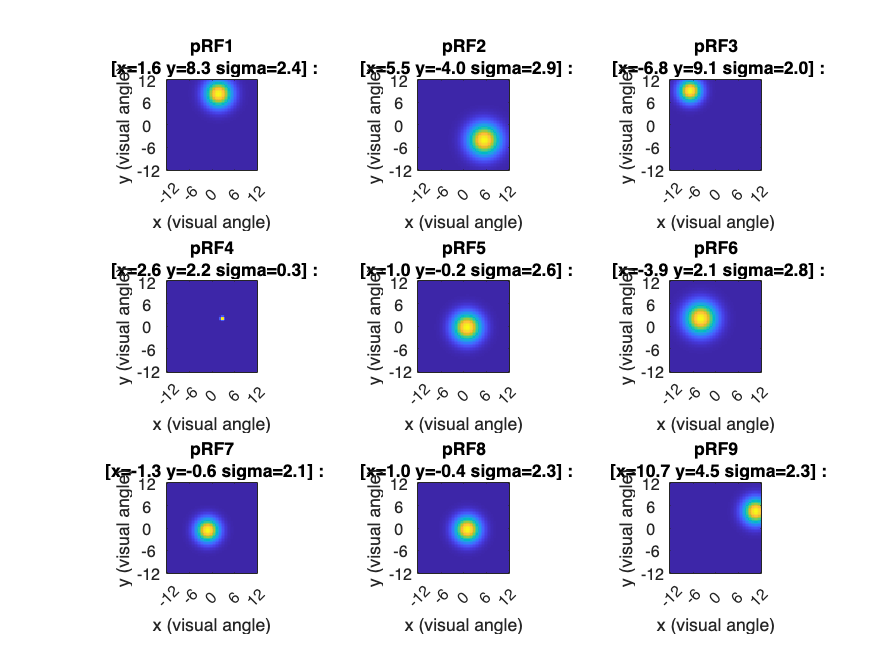

% make a RF grid
x = -StimSize:0.4:StimSize; y = x;
[X,Y] = meshgrid(x,y); XY = [{X},{-1*Y}];

% assign values
x0 = RF(:,1);
y0 = RF(:,2);
sigma = RF(:,3);

% make RF
rf = zeros(61,61,nVoxels);
for vx = 1:nVoxels
    rf(:,:,vx) = pmGaussian2d(XY{1}, XY{2}, ...
                sigma(vx),sigma(vx),0, ...
                x0(vx),y0(vx));
end

% plot 9 pRFs
figure;
for vx = 1:nVoxels
    subplot(3,3,vx);
    imagesc(rf(:,:,vx));
    tickPositions = linspace(1, size(rf(:,:,vx), 1), numel([-12, -6, 0, 6, 12])); % Adjust for appropriate indexing
    set(gca, 'XTick', tickPositions, 'XTickLabel', [-12, -6, 0, 6, 12]); % Set X tick labels
    set(gca, 'YTick', tickPositions, 'YTickLabel', [12, 6, 0, -6, -12]); % Set Y tick labels
    xlabel('x (visual angle)')
    ylabel('y (visual angle)')
    title(sprintf('pRF%d\n [x=%1.1f y=%1.1f sigma=%1.1f] :',vx, x0(vx), y0(vx),sigma(vx)))
    axis square;
end

### Question 3

Create and plot a pRF located at x = 1.3, y= 0.4 with receptive field size (sigma) of 1.2

% Answer here:



### Temporal impulse response functions (IRFs)

We are going to look into temporal impulse response function of the CST (compressive spatiotemporal) pRF model. The CST model has 3 channels, each with a different temporal impulse response function (IRF): sustained, transient-on, and transient-off. The sustained IRF models the ongoing neural responses, while the transient IRFs compute changes and visual transitions/transients. “On” and “Off” responses of the transient IRFs were separately modeled to account for increased neural responses with both stimulus onsets and offsets. These three spatiotemporal channels were designed to capture both prolonged and abrupt changes in neural responses to stimuli at specific locations and sizes.

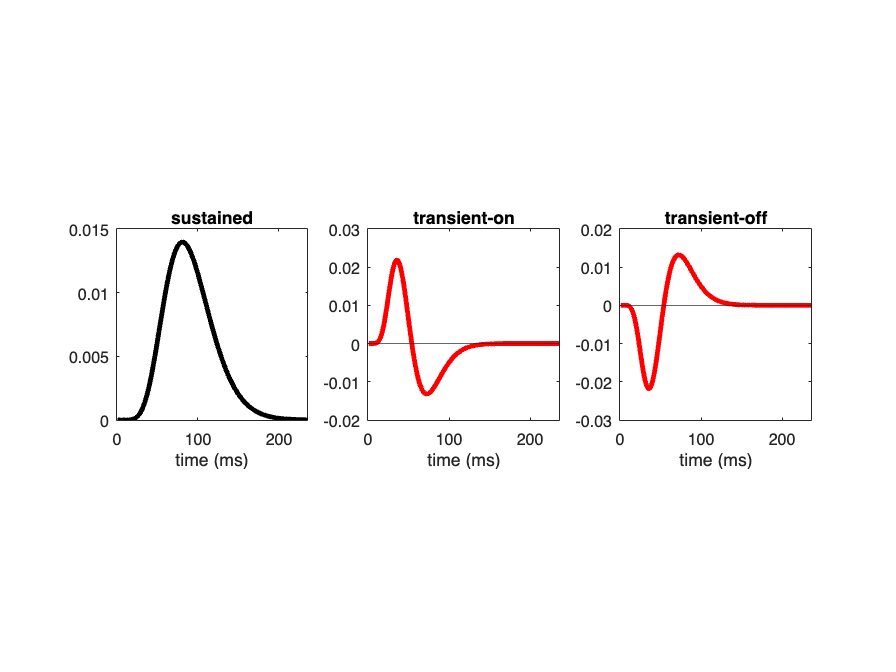

% parameter tau governs time-to-peak (at the rate of 10 hz)
% meaning that tau of 10 is approximately 100 ms for the sustained channel
tau = 10;  
[f, ~] = setTemporalParams( 'CST', tau);

figure;
subplot(131)
plot(f.temporal(:,1),'k','LineWidth',3); axis square; hold on; yline(0)
title('sustained'); xlabel('time (ms)');  
subplot(132)
plot(f.temporal(:,2),'r','LineWidth',3); axis square; hold on; yline(0) 
title('transient-on'); xlabel('time (ms)'); 
subplot(133)
plot(f.temporal(:,3),'r', 'LineWidth',3); axis square; hold on; yline(0)
title('transient-off'); xlabel('time (ms)'); 

### Question 4

Describe the shape/properties of the sustained, transient-on, and transient-off impulse response functions. When comparing the sustained and transient-on impulse response functions, which one is faster?

% Answer here:


### Create spatiotemporal pRFs

Now it's time to create spatiotemporal pRFs! We know that visual neurons integrate stimulus information over visual space and time. How can we model a receptive field that has both a spatial window and a temporal window of response? 

We can create spatiotemporal pRFs by performing a pointwise multiplication of the neural spatial and temporal impulse response functions (Adelson and Bergen, 1985; Watson and Ahumada, 1985). This will generate a 3D pRF; As our spatial pRF is a 2D symmetric Gaussian we will plot a crosssection of the spatial pRF in the y dimension.

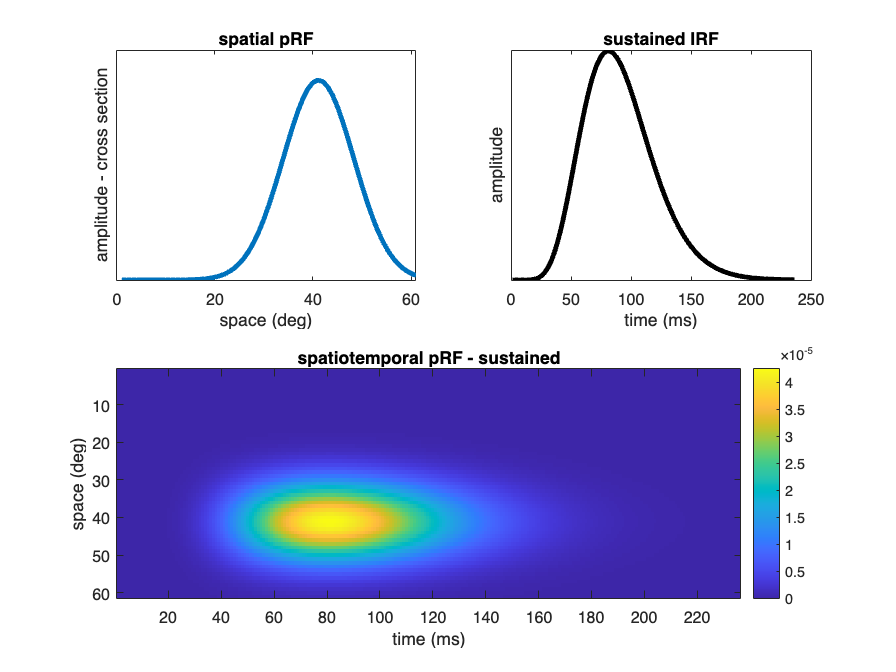

oneRF = rf(:,:,2);
[ ~, ix ] = max(oneRF(:));
[ i1,i2] = ind2sub( size(oneRF), ix );
py = oneRF(:,i2); % cut through one dimension of RF (y-dimension)

tau = 10;
[f, ~] = setTemporalParams( 'CST', tau);
sustained = f.temporal(:,1);
transient_on = f.temporal(:,2);
transient_off = f.temporal(:,3);
stRF_sustained=py*sustained';

figure;
subplot(221)
plot(py,'LineWidth',3); yticks([]); % RF - y dimension 
title('spatial pRF')
xlabel('space (deg)')
ylabel('amplitude - cross section')

subplot(222)
plot(sustained,'k','LineWidth',3); yticks([]);
title('sustained IRF')
xlabel('time (ms)');  
ylabel('amplitude')


% You can see that the spatiotemporal pRF has both space and time as its dimensions.
subplot(2,2,[3 4])
imagesc(stRF_sustained); colorbar
ylabel('space (deg)')
xlabel('time (ms)')
title('spatiotemporal pRF - sustained')

### Question 5

Following the same logic as above, create and plot a spatiotemporal pRF for the stRF_transient_on and stRF_transient_off channels. 

% Following the same logic above, create a spatiotepmoral pRF for
% stRF_transient_on and stRF_transient_off


### Predict fMRI time course 

Finally, it is time to predict spatiotemporal fMRI responses from the stimulus using the CST model. The CST model has three spatial parameters (x y s), a temporal parameter (τ), and a compressive exponent (n), where s is the size of the spatial RF, and τ is the time-to-peak.

The CST model is implemented as follows: first, the dot product is applied between binarized spatiotemporal visual input I(X, Y, t) and the spatial RF at each time point. This effectively computes the weighted sum of the spatial overlap between stimulus at time (t) and the spatial RF. Then, to predict spatiotemporal neural activity, we convolve the output of the spatial pRF with each of the three different temporal impulse response functions (sustained, on-transient, off-transient). Then, the CST model implements two nonlinearities in each channel: (1) a rectified linear unit (ReLU) and (2) a compressive power-law exponentiation.

This is our neural encoding model, predicting the neural response in each channel to the stimulus that changes over time and space.

To predict fMRI responses resulting from each of the sustained and transient neural responses in each channel, we convolve the predicted neural responses over time with the HRF;  We then down sampled to 1 s resolution to match the temporal resolution of our fMRI measurements. The predicted BOLD response is the sum of the sustained and transient responses multiplied by betas of each of the channels. Since this is a simulation we will implement a response where the betas in all channels equal 1;

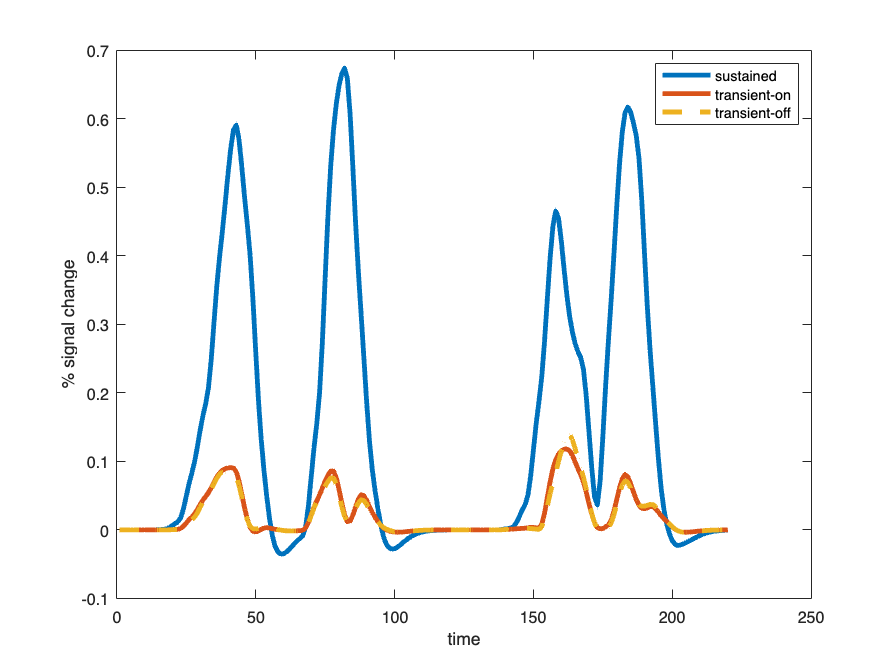

% stimulus 
stim = reshape(stim_ms,size(stim_ms,1)*size(stim_ms,2),[]); % collapse 1st dim 

% RF
oneRF = rf(:,:,1);  
oneRF= oneRF(:); % collapse 1st dim  

% voxel response after spatoal receptive filtering (dot product of stimulus and spatial RF)
s_prfResponse = full(sparse(stim)'* sparse(double(oneRF)));

% voxel response after convolultion with neural temporal impluse response function (IRF) 
tau = 10;
[f, ~] = setTemporalParams( 'CST', tau); % sample by 10 ms 
sustained = f.temporal(:,1);
transient_on = f.temporal(:,2);
transient_off = f.temporal(:,3);

% create st_pRF responses for 3 IRFs
for n = 1:3
    st_prfResponse(:,:,n) = convCutn(s_prfResponse, f.temporal(:,n), size(s_prfResponse,1));
end

% Apply nonlinearity (1): rectify negative components of the transient response,
% as both on and off responses increase the neural firing rate.
st_prfResponse= relu(st_prfResponse, 1, 0, 0);


% Apply nonlinearity (2): compression through static exponentiation (n). 
% This is to account for nonlinear summation in the visual system, which tends to be subadditive.
% here we are just going to set this compression (n) parameter to be 0.5
st_prfResponse = staticExpComp(st_prfResponse, 0.5);


% then we convovle with the canonical spm HRF
params.analysis.hrf.type ='spm';
params.analysis.temporal.fs = 1000;
[hrf,params] = getHRF(params);

% convovle with HRF
predBOLD_tmp = convCutn(st_prfResponse,hrf,size(st_prfResponse,1));
predBOLD = downsample(predBOLD_tmp,  1000);

% plot BOLD responses from:
% - sustained spatiotemporal pRF,
% - transient-on spatiotemporal pRF,
% - transient-off spatiotemporal pRF.
figure;
plot(predBOLD(:,1),'LineWidth',3); hold on
plot(predBOLD(:,2),'LineWidth',3); hold on
plot(predBOLD(:,3),'LineWidth',3,'linestyle','--'); hold on
legend('sustained','transient-on','transient-off')
ylabel('% signal change')
xlabel('time')

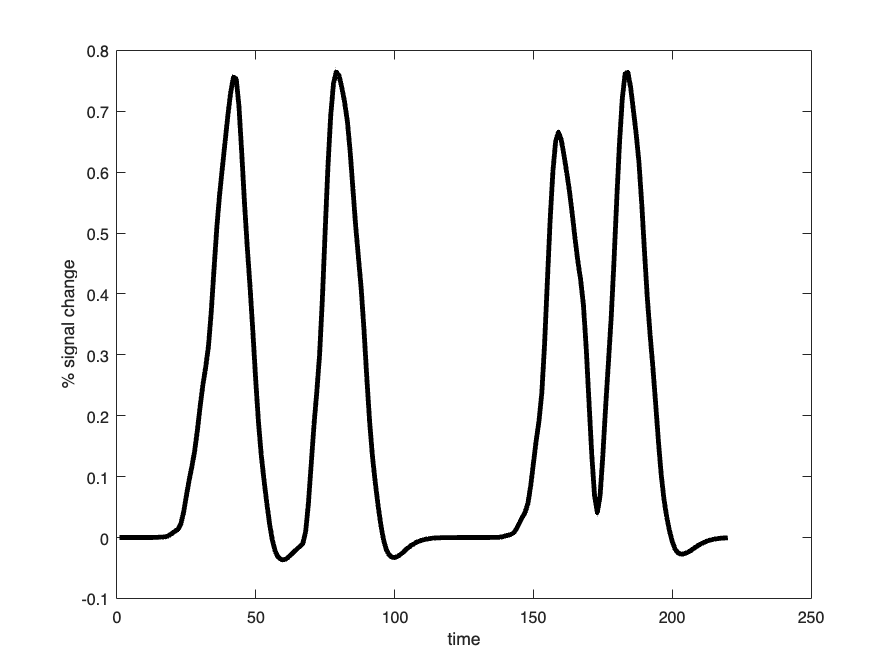

% Finally,the predicted BOLD response is the sum 
% of the responses across all three channels 
% which is plotted below for this voxel.
figure;
plot(sum(predBOLD,2),'k','LineWidth',3)
ylabel('% signal change')
xlabel('time')

### Compute predicted time courses for all 9 voxels and add noise

Now that you know how to compute the expected BOLD signal from the CST model step by step, let's quickly compute everything here. Additionally, let's add some noise to make the time courses more similar to empirical BOLD data. As a bonus, we will also compute predicted BOLD responses using the same method for another spatiotemporal pRF model, which is the delayed normalization spatiotemporal pRF (DN-ST) model. However, in this tutorial, we will only focus on the CST model.

cd(simDir)
noiselevel = 'noise1'; % set noise level 
nVoxels = 9; % simulate 9 voxels

% create randomized extra params for a specfic model [tau, n]
tParam1 = randomTemporalparam('CST',nVoxels); % CST model
tParam2 = randomTemporalparam('DN-ST',nVoxels); % DN model 

% load pre-defined jsonfiles
jsonTemplate = fullfile('template','template.json');

% manipulate json files with these randomly generated params
jsonDir = fullfile(resultsDir,'jsonfiles');  
temporalSampleRate =100;
if ~exist(jsonDir, 'dir'), mkdir(jsonDir);end
randjson(jsonDir,jsonTemplate,nVoxels,expNames,stimFiles, ...
    StimSize,temporalSampleRate,RF,tParam1,tParam2,noiselevel);

%% synthetic BOLD generation
jFiles2 = getAllFiles2(jsonDir, sprintf('*.json'),2);
for jj = 1:length(jFiles2)
    json = jFiles2{jj};
    [~,jsonname]=fileparts(json);
    outputDir = fullfile(resultsDir,'synthBOLD',jsonname);
    DTcalc = synthBOLDgenerator(json,outputDir);
end

There are 3 voxels 
1 -- 2 -- 3
Elapsed time is 0.695357 seconds.
Concatenating the .mat files back


There are 3 voxels 
1 -- 2 -- 3
Elapsed time is 0.434522 seconds.
Concatenating the .mat files back


There are 3 voxels 
1 -- 2 -- 3
Elapsed time is 0.426714 seconds.
Concatenating the .mat files back


There are 3 voxels 
1 -- 2 -- 3
Elapsed time is 0.432373 seconds.
Concatenating the .mat files back


There are 3 voxels 
1 -- 2 -- 3
Elapsed time is 0.489185 seconds.
Concatenating the .mat files back


There are 3 voxels 
1 -- 2 -- 3
Elapsed time is 0.450309 seconds.
Concatenating the .mat files back


There are 3 voxels 
1 -- 2 -- 3
Elapsed time is 0.491522 seconds.
Concatenating the .mat files back


There are 3 voxels 
1 -- 2 -- 3
Elapsed time is 0.482758 seconds.
Concatenating the .mat files back


There are 3 voxels 
1 -- 2 -- 3
Elapsed time is 0.470166 seconds.
Concatenating the .mat files back


%% gather and clean BOLD files
removeFirstBlankSignals = 10;  % remove fist 10 TRs where it is just blank screen
rfiles = getAllFiles(fullfile(resultsDir,'synthBOLD'),sprintf('*table.mat'),1);
st_cleanDT(rfiles,resultsDir,removeFirstBlankSignals);

%% visualize synthetic timecourse
t = load(fullfile(resultsDir,'data/GT.mat'));

DT = t.DT{1}; % just get the CST model 

% This is the ground truth data for the 9 simulated voxels
% view table - it has all the parameters and timecourse without noise (tc) and with noise (ntc) 
head(DT)

    voxel              RF               tmodel               tparam                SNR          ntc              tc     
    _____    _______________________    _______    __________________________    _______    ____________    ____________

      1       1.61     8.31     2.42    {'CST'}    {[82.2100 82.2100 0.9700]}    0.17809    1×210 double    1×210 double
      2        5.5    -4.05     2.89    {'CST'}    {[90.9600 90.9600 0.2400]}     12.242    1×210 double    1×210 double
      3      -6.78      9.1     2.04    {'CST'}    {[16.1900 16.1900 0.9700]}    -2.3465    1×210 double    1×210 double
      4       2.59     2.18      0.3    {'CST'}    {[91.6800 91.6800 0.9600]}      6.549    1×210 double    1×210 double
      5       0.96    -0.19     2.5

### Inspect timecourses for voxel number 4

voxelNumber = 4; 
fprintf('RF locations: [x = %1.1f ,y = %1.1f], RF size [sigma = %1.1f]', DT(voxelNumber,:).RF);

RF locations: [x = 2.6 ,y = 2.2], RF size [sigma = 0.3]

fprintf('temporal IRF: (tau) [τ = %1.1f]', DT(voxelNumber,:).tparam{1}(1));

temporal IRF: (tau) [τ = 91.7]

fprintf('nonlinearity: compression (n) [n = %1.1f]', DT(voxelNumber,:).tparam{1}(3));

nonlinearity: compression (n) [n = 1.0]

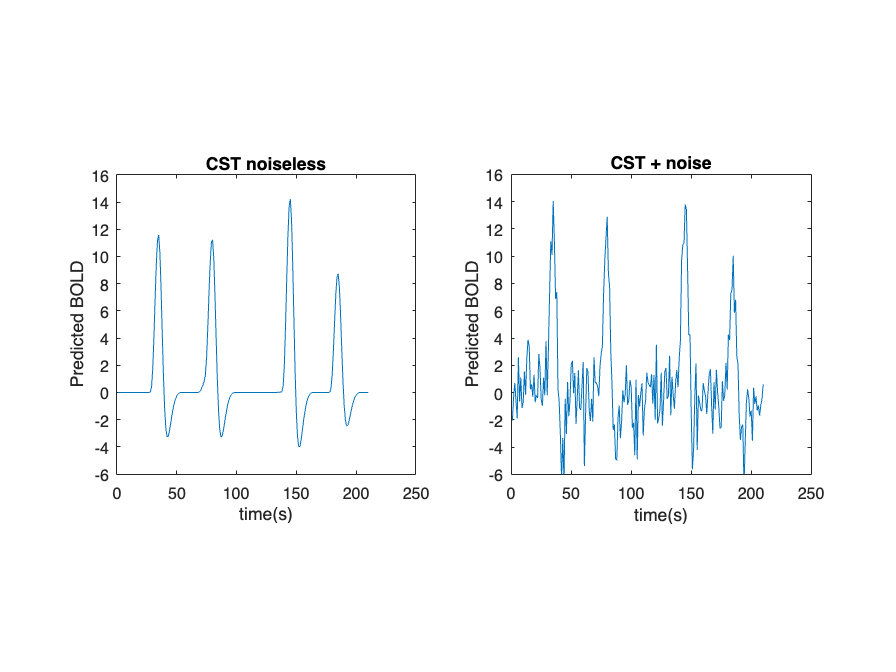

% CST model
figure;
subplot(121);
plot(DT(voxelNumber,:).tc)
model =DT(voxelNumber,:).tmodel{1};
title(sprintf('%s noiseless',model));
xlabel('time(s)'); ylabel('Predicted BOLD'); axis square;
ylim([-6,16]);
subplot(122);
plot(DT(voxelNumber,:).ntc)
title(sprintf('%s + noise',model))
xlabel('time(s)'); ylabel('Predicted BOLD'); axis square;
ylim([-6,16]);

### Inspect timecourses for voxel number 6

voxelNumber = 6; 
fprintf('RF locations: [x = %1.1f ,y = %1.1f], RF size [sigma = %1.1f]', DT(voxelNumber,:).RF);

RF locations: [x = -3.9 ,y = 2.1], RF size [sigma = 2.8]

fprintf('temporal IRF: (tau) [τ = %1.1f]', DT(voxelNumber,:).tparam{1}(1));

temporal IRF: (tau) [τ = 13.4]

fprintf('nonlinearity: compression (n) [n = %1.1f]', DT(voxelNumber,:).tparam{1}(3));

nonlinearity: compression (n) [n = 0.8]

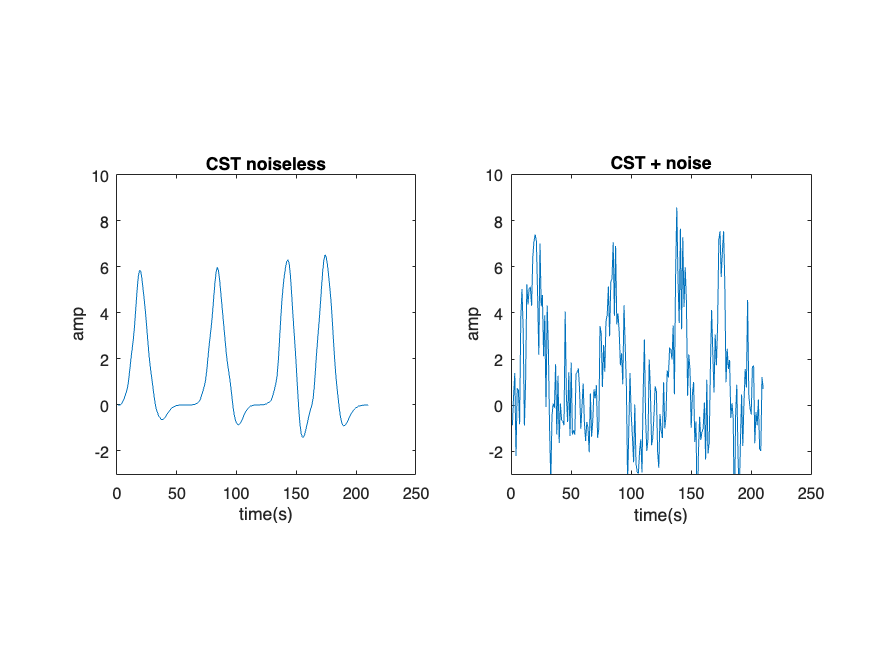

% CST model
figure;
subplot(121);
plot(DT(voxelNumber,:).tc)
model =DT(voxelNumber,:).tmodel{1};
title(sprintf('%s noiseless',model));
xlabel('time(s)'); ylabel('amp'); axis square;
ylim([-3,10]);

subplot(122);
plot(DT(voxelNumber,:).ntc)
title(sprintf('%s + noise',model))
xlabel('time(s)'); ylabel('amp'); axis square;
ylim([-3,10]);

### Question 6

Depending on the combinations of the parameters, the predicted time courses vary. Describe how the time courses for voxel number 4 and voxel number 6 differ.

% answer here:



## Solve spatiotemporal pRF model

One interesting question we can now ask is the inverse: given a time course and stimulus, can we recover its ground-truth parameters? In the actual experiment, the stimulus and observed time courses are all we have, and we want to infer each voxel's underlying parameters that describe its characteristics. These characteristics tell us where the RF is located, its size, and its time-to-peak, and amount of compression.

Using the noise added timecourses that we generated above, let's try to solve the spatiotemporal pRF model and check if we can recover the ground-truth parameters.

% [WARNING] This will take a while --> go get a coffee / tea / beer / boba / insub (even if you don't know me).
% It may take up to an hour or two (unless you have a GPU on your computer).
useGPU = 0; % <----- if you have gpu change this to be 1

% set mrVista files
cd(simDir)
dataTemplate = fullfile('./template','data_template');
copyfile(dataTemplate,fullfile(resultsDir,'data'))
copyfile('./Stimuli',fullfile(resultsDir,'data','Stimuli'))

load(fullfile(resultsDir,'data','mrSESSION_template.mat'))
mrSESSION.functionals.totalFrames = 220;  %%%  need to set this
dataTYPES.scanParams.nFrames = mrSESSION.functionals.totalFrames - 10; %%%  need to set this
sp = dataTYPES.scanParams;
f =  mrSESSION.functionals;

for i =  1:nRuns
    dataTYPES.scanParams(i) = sp;
    mrSESSION.functionals(i) = f;
end
save(fullfile(resultsDir,'data','mrSESSION.mat'),'dataTYPES','mrSESSION','vANATOMYPATH')
load(fullfile(resultsDir,'data','mrSESSION.mat'))

roifile = [];
stimfile = getAllFiles('./Stimuli','images_and_params*',1);
analysisoption = 5; % all
prfModel = 'st';
subjNumber=1;
wSearch = 8;

temporalModels = {'CST'};
% actually start solving
for tm = 1:length(temporalModels)
    temporalModel =  temporalModels{tm};
    userData = sprintf('bold_%s_voxel-all.mat',temporalModel);
    st_prfRun(sessionDir,roifile,stimfile,analysisoption, ...
    prfModel,temporalModel,sprintf('subj%02d', subjNumber),wSearch, ...
    userData,useGPU)
end
% create results table
cd(fullfile(simDir,sessionDir))
rfiles = getAllFiles('./Gray/simulation_result/simulation', ...
                     sprintf('*sFit.mat'),2);
estimated_table = st_sim_makeSessionTable(fullfile(simDir,sessionDir),rfiles,'gray');

### Ground-truth vs recovered parameters

The moment of truth. Given only the stimulus and time courses, can we recover the underlying spatiotemporal parameters?

% gt: ground-truth table
% pt: predicted table (model estimated)
cd(fullfile(simDir,sessionDir))
estimated_table = Constants.getDir.sim_pt;
pt = load(estimated_table); % predicted table
pt = pt.DT;
gt = load(fullfile(simDir,sessionDir,'GT.mat')); % ground truth table
gt = gt.DT{1};
[pt_params, gt_params]= extract_params(pt,gt);

mycolor = getmycolors(1);
tmn  = {'spatial','DN-ST','CST'};
param_names   = {'\itx','\ity','\sigma','\tau', '\itn'};
param_units = {'deg', 'deg', 'deg', 's', 'a.u'};
% plot it
for s = 1:length(param_names)
    subplot(2,3,s)
    scatter(gt_params(:,s),pt_params(:,s), ...
        'MarkerEdgeColor',mycolor(3,:), ...
        'MarkerFaceColor',mycolor(3,:)); hold on; 
    axis square;
    ylabel([param_names{s},' prediction']);
    xlabel([param_names{s},' ground-truth']);
 
    if s <3
        xy = [-15 15];
        xlim([-15 15])
        ylim([-15 15])
        xticks([-10:5:10]);
        yticks([-10:5:10]);
    elseif s == 3
        xy = [0 6];
        xlim([0 5])
        ylim([0 5])
        xticks([0:5]);
        yticks([0:5]);

    else
        TickL = [0 0.5 1];
        xticks(TickL);
        yticks(TickL);
        xlim([min(TickL) max(TickL)]);
        ylim([min(TickL) max(TickL)]);
        xy = [min(TickL)  max(TickL)];
    end
    line(xy,xy,'Color','k','LineWidth',1.5,'LineStyle','--'); hold on;
    title(sprintf('%s (%s)',param_names{s},param_units{s}))
end

### Question 7

How accurately are the recovered  spatial (x,y, sigma) and temporal (tau (τ)) parameters of the 9 simulated voxels vs. the ground truth? Which parameters are well recovered and which less so? 

Focuing on the temporal parameter (τ), as you can see, from the sluggish simulated fMRI response, we have attempted to recover fine-grained sub-second temporal parameters (see units of the x-axis and y-axis). So, what do you think? Is it possible to obtain millisecond resolution from fMRI data after all? What do you think?

% answer here


### Question 8

Remember that we are recovering the pRF parameters from just one run's worth of data (220-s experiment). Typically, we obtain more data points to boost our estimation as the data is noisy. Do you think it is feasible to achieve reliable parameter estimations with such limited data? Would the parameter recovery get better if we obtain more runs?

 % answer here




### Question 10: Extra credit.

For each parameter calculate and report the % error of the parameter estimate vs. ground truth value. Predicted parameters: pt_params; Ground truth parameters: gt_params; How does this compare to [Figure 4D in Kim et al. 2024](https://www.jneurosci.org/content/jneuro/44/2/e0803232023/F4.large.jpg)?

 % answer here





function [pt_params, gt_params ]= extract_params(pt,gt)
    
    pt_temporal_param = cell2mat(pt.temporal);
    % we divide time unit by 100 to convert time unit from 10 ms to seconds.
    pt_tau = pt_temporal_param(:,1)/100; 
    pt_params = [pt.x0 pt.y0 pt.sigma pt_tau pt.exponent]; 
    
    gt_temporal_param = cell2mat(gt.tparam);
    gt_tau = gt_temporal_param(:,1)/100;
    gt_n = gt_temporal_param(:,3);
    gt_params = [gt.RF gt_tau gt_n];

end

function [f, params] = setTemporalParams(model, tau, fs)
    if notDefined('fs')
        fs = 1000;
    end
    params.analysis.temporalModel = model;
    params.analysis.spatial.values = 0;
    params = getTemporalParams(params);
    
    params.analysis.temporal.fs = fs;
    params.analysis.temporal.param.fs = fs;
    params.analysis.temporal.param.tau_s = tau;
    params.useGPU = 0;
    [f, params] = get3DSpatiotemporalpRFs(params);
   
end
